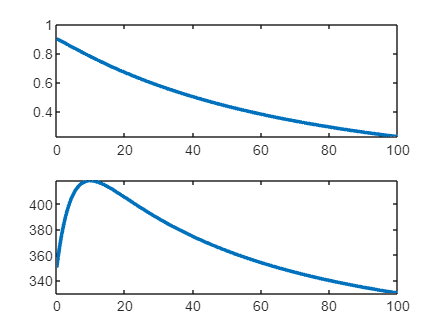

[xdat, ydat] = ode_rk4e('batch_poly', [0.9 350], 0.1, 100);
subplot(2,1,1)
plot(xdat, ydat(:,1), '-','LineWidth',2)
subplot(2,1,2)
plot(xdat, ydat(:,2), '-','LineWidth',2)

function [xdat, ydat] = ode_rk4e(fun, y, dt, tmax)
t = 0; sc = 0; j = 1; rt = tmax/200; t_int = fix(rt/dt); n = 1+fix(tmax/dt);
ydat = zeros(201,2); xdat = zeros(201,1); ydat(1,:) = y; xdat(1) = t;
if (t_int<1)
    t_int = 1;
end
for i = 1:n
    k1 =eval([fun, '(t, y)']);
    y1 = y+k1*dt/2.; t1 = t+dt/2.; k2 = eval([fun, '(t1, y1)']);
    y1 = y+k2*dt/2.; k3 = eval([fun, '(t1, y1)']);
    y1 = y+k3*dt/2.; t1 = t+dt; k4 = eval([fun, '(t1, y1)']);
    y = y + (dt/6.)*(k1+2*k2+2*k3+k4);
    sc =sc + 1; t = t + dt;
    if(sc == t_int)
        j = j + 1; ydat(j,:) = y; xdat(j) = t; sc = 0;
    end
end
end

function [dz] = batch_poly(t,z)
dz = [0 0];
U = 300; k0 = 0.03; b = 285; Tc = 300;
x = z(1); T = z(2);
dz(1) = -k0*x*exp(-b/T);
dz(2) = (-3e6*10*dz(1)-U*10*(T-Tc))/10/1000;
end